# Test Edges for Fillet

## Brief summary of this function

Tests whether the three edges which are subject to a filleting operation via optimization can be correctly queried using the `PythonOCC`-geometry object

function testEdges4Fillet(testCase)

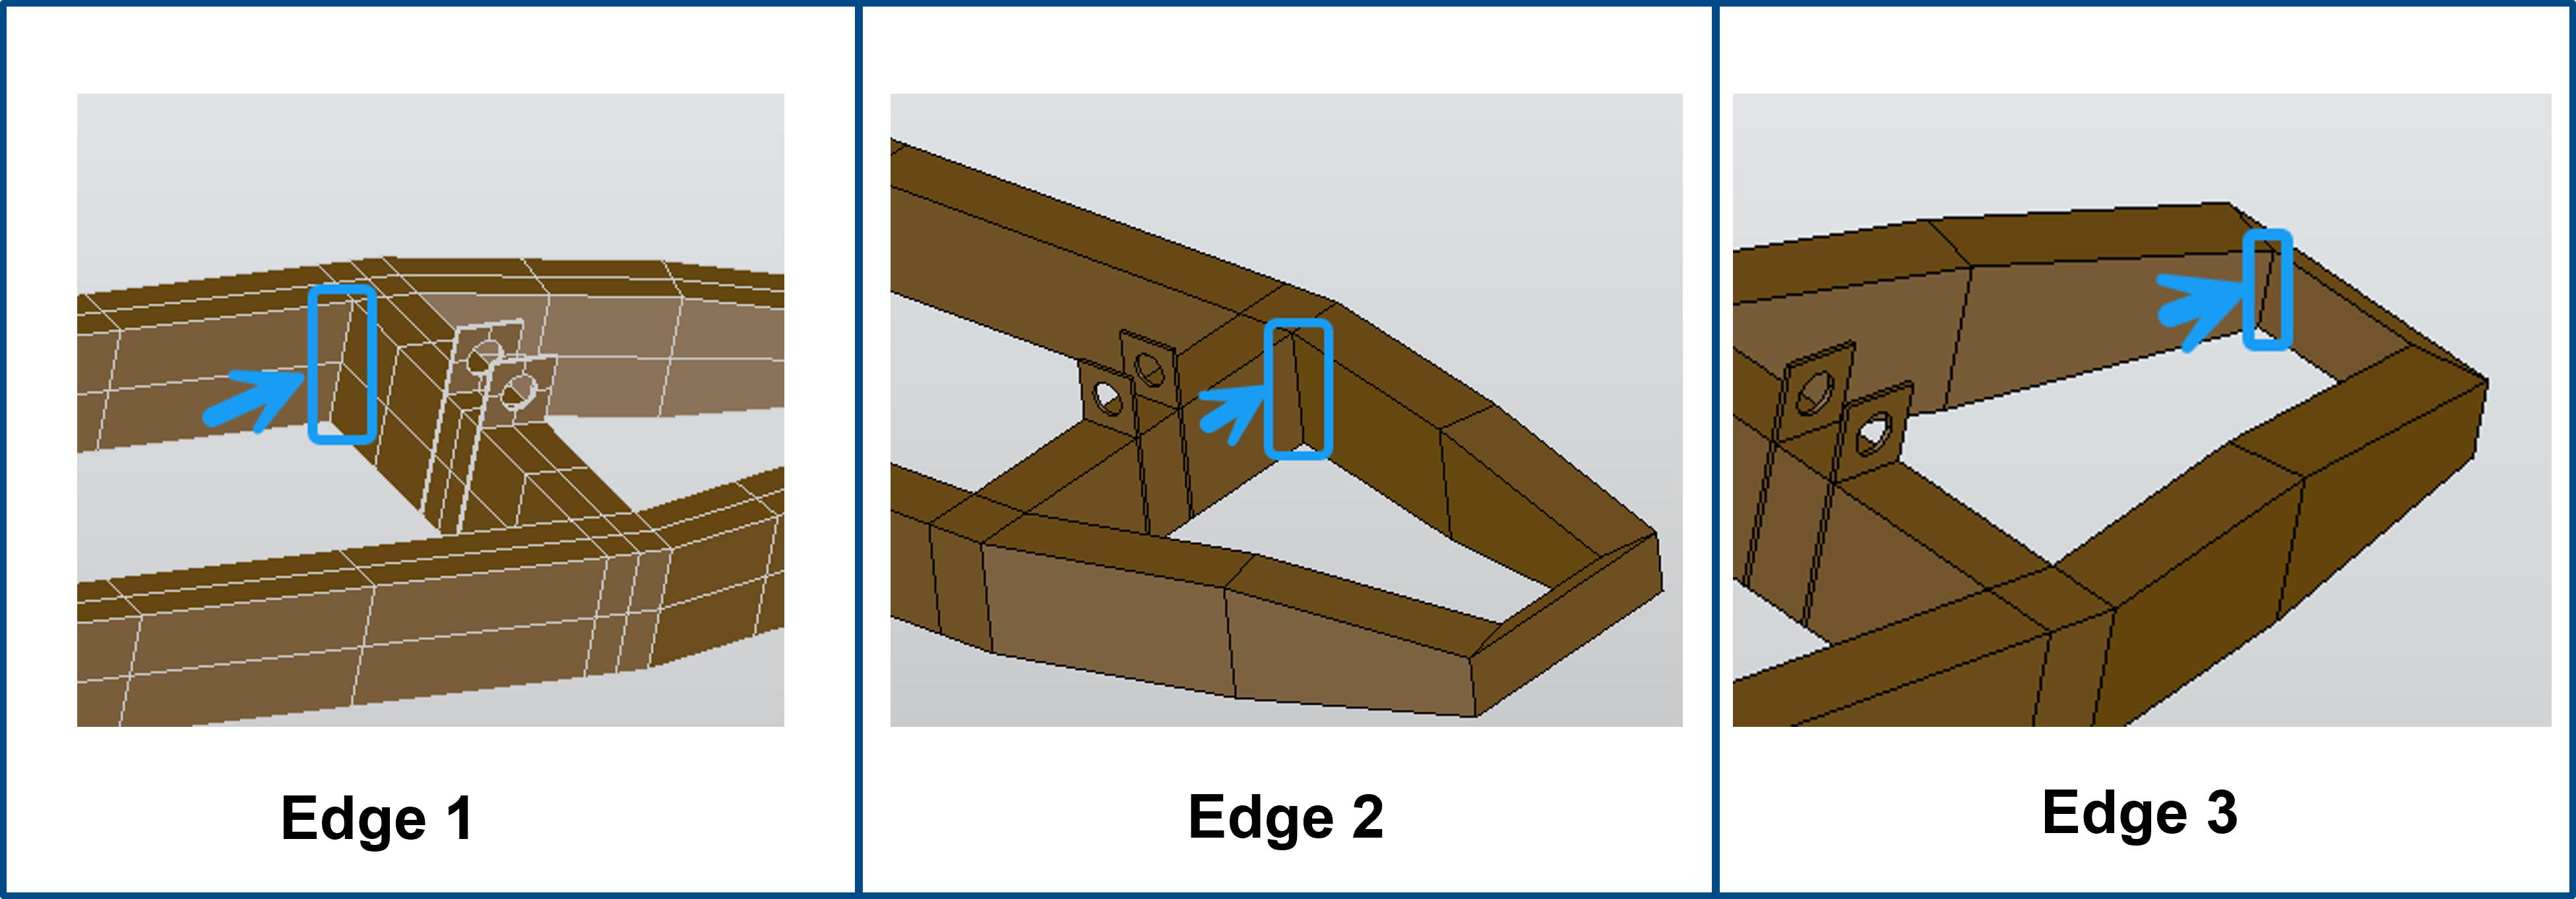

## Definition of tolerances

tol = 1e-15;
tol3 = tol*1e3;

## Compute the properties of edge 1

### Find the selected edge and construct the design variables

edgeID1 = 34;
testCase.geometryObj.selectedEdges = py.list([]);
edge1 = getSelectedEdge(testCase.geometryObj.baseShape, edgeID1);
testCase.geometryObj.selectedEdges.append(edge1)
testCase.geometryObj.getDataDesignVariables(py.int(0))
testCase.geometryObj.computeNumDesignVariables()

### Get the start and the end coordinates of the curve

edgeParams1 = py.OCC.Core.BRep.BRep_Tool.Curve(testCase.geometryObj.selectedEdges{1});
curveHdl1 = edgeParams1{1};
startPt1 = curveHdl1.Value(edgeParams1{2});
startPt1 = [startPt1.X, startPt1.Y, startPt1.Z];
endPt1 = curveHdl1.Value(edgeParams1{3});
endPt1 = [endPt1.X, endPt1.Y, endPt1.Z];

### Get the coordinates of the design variables

pointCoords1 = cell(testCase.geometryObj.pointCoords);
numEl1 = cellfun(@(x) double(py.len(x)), pointCoords1);
if any(diff(numEl1))
    error("The Python list 'pointCoords' does not represent a matrix")
end
pointCoords1 = reshape(cell2mat(cellfun(@double, pointCoords1, 'UniformOutput', false)), numEl1(1), [])';

## Compute the properties of edge 2

### Find the selected edge and construct the design variables

edgeID2 = 11;
testCase.geometryObj.selectedEdges = py.list([]);
edge2 = getSelectedEdge(testCase.geometryObj.baseShape, edgeID2);
testCase.geometryObj.selectedEdges.append(edge2)
testCase.geometryObj.getDataDesignVariables(py.int(0))
testCase.geometryObj.computeNumDesignVariables()

### Get the start and the end coordinates of the curve

edgeParams2 = py.OCC.Core.BRep.BRep_Tool.Curve(testCase.geometryObj.selectedEdges{1});
curveHdl2 = edgeParams2{1};
startPt2 = curveHdl2.Value(edgeParams2{2});
startPt2 = [startPt2.X, startPt2.Y, startPt2.Z];
endPt2 = curveHdl2.Value(edgeParams2{3});
endPt2 = [endPt2.X, endPt2.Y, endPt2.Z];

### Get the coordinates of the design variables

pointCoords2 = cell(testCase.geometryObj.pointCoords);
numEl2 = cellfun(@(x) double(py.len(x)), pointCoords2);
if any(diff(numEl2))
    error("The Python list 'pointCoords' does not represent a matrix")
end
pointCoords2 = reshape(cell2mat(cellfun(@double, pointCoords2, 'UniformOutput', false)), numEl2(1), [])';

## Compute the properties of edge 3

### Find the selected edge and construct the design variables

edgeID3 = 3;
testCase.geometryObj.selectedEdges = py.list([]);
edge3 = getSelectedEdge(testCase.geometryObj.baseShape, edgeID3);
testCase.geometryObj.selectedEdges.append(edge3)
testCase.geometryObj.getDataDesignVariables(py.int(0))
testCase.geometryObj.computeNumDesignVariables()

### Get the start and the end coordinates of the curve

edgeParams3 = py.OCC.Core.BRep.BRep_Tool.Curve(testCase.geometryObj.selectedEdges{1});
curveHdl3 = edgeParams3{1};
startPt3 = curveHdl3.Value(edgeParams3{2});
startPt3 = [startPt3.X, startPt3.Y, startPt3.Z];
endPt3 = curveHdl3.Value(edgeParams3{3});
endPt3 = [endPt3.X, endPt3.Y, endPt3.Z];

### Get the coordinates of the design variables

pointCoords3 = cell(testCase.geometryObj.pointCoords);
numEl3 = cellfun(@(x) double(py.len(x)), pointCoords3);
if any(diff(numEl3))
    error("The Python list 'pointCoords' does not represent a matrix")
end
pointCoords3 = reshape(cell2mat(cellfun(@double, pointCoords3, 'UniformOutput', false)), numEl3(1), [])';

## Tests

### Test the properties of edge 1

expPtStart1 = [4.376799287066853e+02, -30, -68.760325382890272];
testCase.verifyEqual(startPt1, expPtStart1, 'AbsTol', tol3);
expPtEnd1 = [4.521737952323418e+02, -30, -1.228521716551008e+02];
testCase.verifyEqual(endPt1, expPtEnd1, 'AbsTol', tol3);
expPointCoords1 = readmatrix("pointCoords1.txt");
testCase.verifyEqual(pointCoords1, expPointCoords1, 'AbsTol', tol3);

### Test the properties of edge 2

expPtStart2 = [4.666577034953576e+02, -30, -60.995754029814663];
testCase.verifyEqual(startPt2, expPtStart2, 'AbsTol', tol3);
expPtEnd2 = [4.811515700210987e+02, -30, -1.150876003020025e+02];
testCase.verifyEqual(endPt2, expPtEnd2, 'AbsTol', tol3);
expPointCoords2 = readmatrix("pointCoords2.txt");
testCase.verifyEqual(pointCoords2, expPointCoords2, 'AbsTol', tol3);

### Test the properties of edge 3

expPtStart3 = [6.862474147177610e+02, -85.802754554007379, -15.615458586919260];
testCase.verifyEqual(startPt3, expPtStart3, 'AbsTol', tol3);
expPtEnd3 = [6.940119860708365e+02, -85.802754554007379, -44.593233375591318];
testCase.verifyEqual(endPt3, expPtEnd3, 'AbsTol', tol3);
expPointCoords3 = readmatrix("pointCoords3.txt");
testCase.verifyEqual(pointCoords3, expPointCoords3, 'AbsTol', tol3);

end